# 矩阵的创建方法

`在`MATLAB`中，矩阵的创建方法主要有三种，分别是：直接输入法、函数创建法和导入本地文件中的数据。`

## `（1）``直接输入法`

`输入矩阵时要以中括号“``[ ]``”作为标识符号，矩阵的所有元素必须都在中括号内。`

`矩阵的同行元素之间用空格或逗号分隔，行与行之间用分号或回车键分隔。`

clc;clear
a = [1 2 3; 4 5 6]

a =      1     2     3
     4     5     6


b = [1,2,3; 4,5,6]

b =      1     2     3
     4     5     6


c = [2  5
    6  7]

c =      2     5
     6     7


d = [3 6;
    6 9]   % 还可以既加分号又加回车键进行换行

d =      3     6
     6     9


e = [1 2 3;4 5 6; 2 3 4]

e =      1     2     3
     4     5     6
     2     3     4


`如果不想显示输出结果，可以在语句的最后用英文分号“;”结束。（工作区还是可以找到我们创建的矩阵）`

f = [2, 3
     5, 7]

f =      2     3
     5     7


## `（`**2**`）函数创建法`

MATLAB`提供了一些函数，这些函数可以用来生成某些特定的矩阵，我们这里介绍几个最常用到的函数。`

`第一组函数：`** zeros**`、`**ones**`和`**eye**`。`

`这三个函数可用来分别创建全为`0`的矩阵、全为`1`的矩阵和单位矩阵。`

`以`zeros`函数为例，其常见的用法有两种：`

`（`1`）`zeros(n)`可以创建一个`n`行`n`列全为`0`的矩阵；`

`（`2`）`zeros(m,n)`可以创建一个`m`行`n`列全为`0`的矩阵。`

a = zeros(3)

a =      0     0     0
     0     0     0
     0     0     0


b = zeros(2,3)

b =      0     0     0
     0     0     0


c = ones(5)

c =      1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1


d = ones(1,4)

d =      1     1     1     1


单位矩阵：主对角线元素为 1 且其他位置元素为 0 。

e = eye(4)   % 单位矩阵  

e =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


f = eye(4,3)  

f =      1     0     0
     0     1     0
     0     0     1
     0     0     0


g = eye(3,4)  

g =      1     0     0     0
     0     1     0     0
     0     0     1     0


`第二组函数：` **rand**`、`**randi**`和`**randn**`。`

`这三个函数分别用来创建均匀分布的随机数、均匀分布的随机整数和标准正态分布的随机数，以后会大量用到，请大家熟记。（数据的分布是概率论里面的知识点，没学过的同学可以搜索关键词自学）`

MATLAB中的随机数专题：[https://ww2.mathworks.cn/help/matlab/random-number-generation.html](https://ww2.mathworks.cn/help/matlab/random-number-generation.html)

`（这里涉及到了一点概率论的知识，没学过的同学可以搜索关键词自学）`

**rand**`函数``可用来创建区间`0`和`1`内均匀分布的随机数，其最常用的方法有两种：`

`（`1`）`rand(n)`可以创建一个`n`行`n`列的随机数矩阵；`

`（`2`）`rand(m,n)`可以创建一个`m`行`n`列的随机数矩阵。`

`由`rand`函数创建的随机数矩阵的每个元素都随机取样自`0`和`1`之间的均匀分布。`

rand(3)

ans =     0.8147    0.9134    0.2785
    0.9058    0.6324    0.5469
    0.1270    0.0975    0.9575


rand(3,2)

ans =     0.9649    0.9572
    0.1576    0.4854
    0.9706    0.8003


**randi**`函数``是用来创建``均匀分布``的随机``整数``，其最一般的使用方法为：`randi([imin,imax],m,n)`，可以用来创建一个`m`行`n`列的随机数矩阵，该随机数矩阵中的每个元素都是从区间`[imin,imax]`内随机抽取的整数。`

`举个例子，假设我们要模拟投掷`100`次骰子，骰子有`6`个面，那么我们可以使用`randi([1,6],1,100)`得到一个长度为`100`的行向量，向量中的每个元素都是取自`1,2,3,4,5,6`中的一个整数。`

randi([1,6],1,100)  % 这里我生成一个行向量，也可以生成列向量，大家可以根据你自己的需求来。

ans =      1     3     6     5     6     4     1     6     6     5     5     5     3     4     2     5     1     2     1     1     5     5     2     6     1     3     3     5     5     2     3     3     4     5     5     2     5     4     1     1     3     6     3     4     2     5     2     4     5     6


`另外，如果`**imin**`等于`**1**`，那么可以简写为`**randi(imax,m,n)**`；`

randi(6,1,100)

ans =      5     4     6     1     3     1     6     1     5     5     6     1     3     2     5     3     6     2     2     1     1     6     4     4     1     6     4     3     4     3     1     2     1     2     2     3     1     6     6     3     3     3     6     3     1     5     3     2     3     1


`如果`m`和`n`相同，即生成一个`n`行`n`列的方阵，那么可以直接写成`randi([imin,imax],n)`。`

randi([-3 3],5)  

ans =     -2    -1     3     1    -3
    -2     3     0    -2    -1
    -2     0    -3     1    -1
    -2    -2    -2     1    -1
     0     3    -1    -2     0


**randn**`函数``用来创建``标准正态分布``的随机数，其使用方法和`rand`函数类似：`

`（`1`）`randn(n)`可以创建一个`n`行`n`列的随机数矩阵；`

`（`2`）`randn(m,n)`可以创建一个`m`行`n`列的随机数矩阵。`

`由`randn`函数创建的随机数矩阵的每个元素都随机取样自标准正态分布。`

`标准正态分布:以0为均值、以1为标准差的正态分布，记为N(0,1).`

randn(3)

ans =    -3.0292   -1.0667   -0.0290
   -0.4570    0.9337    0.1825
    1.2424    0.3503   -1.5651


randn(2,3)

ans =    -0.0845    0.0983   -0.7342
    1.6039    0.0414   -0.0308


`第三组函数：`**diag**`和`**blkdiag**`。`

**diag**`函数可用来创建对角矩阵或者获取矩阵的对角元素。`

`情况1：如果输入的第一个参数是向量，则表示创建对角矩阵。`

`    diag(v,k) 将向量v的元素放置在第k条对角线上，其他位置元素为0。`

    `k=0 表示主对角线(常用)，``k>0 位于主对角线上方，k<0 位于主对角线下方``。`

`    如果k=0, 可以直接写成diag(v)。`

diag([1,2,3])  % 或者写成diag([1,2,3], 0)  

ans =      1     0     0
     0     2     0
     0     0     3


diag([1,2,3],-1)  

ans =      0     0     0     0
     1     0     0     0
     0     2     0     0
     0     0     3     0


diag([1,2,3],2)

ans =      0     0     1     0     0
     0     0     0     2     0
     0     0     0     0     3
     0     0     0     0     0
     0     0     0     0     0


`情况2：`**如果输入的第一个参数是矩阵，则表示获取矩阵的对角元素**`。`

`    diag(A,k) 返回A的第k条对角线上元素的构成的列向量。`

`    k表示对角线编号，我们将其指定为一个整数。`

`    k=0 表示主对角线，k>0 位于主对角线上方，k<0 位于主对角线下方。`

`    如果k=0, diag(A, 0)可以直接写成diag(A)。`

A = [1,2,3,4;5,6,7,8;9,10,11,12;13,14,15,16]

A =      1     2     3     4
     5     6     7     8
     9    10    11    12
    13    14    15    16


diag(A)

ans =      1
     6
    11
    16


diag(A,-1)

ans =      5
    10
    15


diag(A,1)

ans =      2
     7
    12


**blkdiag**`函数可用来创建`**分块对角矩阵**`。`

`分块对角矩阵是相对于常规的对角矩阵而言的，常规的对角矩阵沿对角线具有单个元素，而分块对角矩阵的对角线的元素是矩阵。`

`我们可采用以下形式表示一个分块对角矩阵：`


$$\left\lbrack \begin{array}{cccc}
\textrm{A1} & 0 & \cdots  & 0\\
0 & \textrm{A2} & \cdots  & 0\\
\vdots  & \vdots  & \ddots  & \vdots \\
0 & 0 & \cdots  & \textrm{AN}
\end{array}\right\rbrack$$


A1 = [1,2,3;4,5,6]

A1 =      1     2     3
     4     5     6


A2 = [7,8;9,10]

A2 =      7     8
     9    10


A3 = [11,12;13,14;15,16]

A3 =     11    12
    13    14
    15    16


blkdiag(A1,A2,A3)

ans =      1     2     3     0     0     0     0
     4     5     6     0     0     0     0
     0     0     0     7     8     0     0
     0     0     0     9    10     0     0
     0     0     0     0     0    11    12
     0     0     0     0     0    13    14
     0     0     0     0     0    15    16


## `（`**3**`）导入本地文件中的数据`

MATLAB`可读取本地的文件，支持的常见格式如下：`

- .txt`、`.dat `或` .csv`（适用于带分隔符的文本文件）`

- .xls`、`.xlsb`、`.xlsm`、`.xlsx`、`.xltm`、`.xltx `或` .ods`（适用于电子表格文件）`

`由于这一块的内容比较丰富且可能涉及我们没学过的知识点，所以会放在后面的章节进行讲解。`

`到时候我们会重点学习`MATLAB`菜单栏：“主页——导入数据”这个功能。`

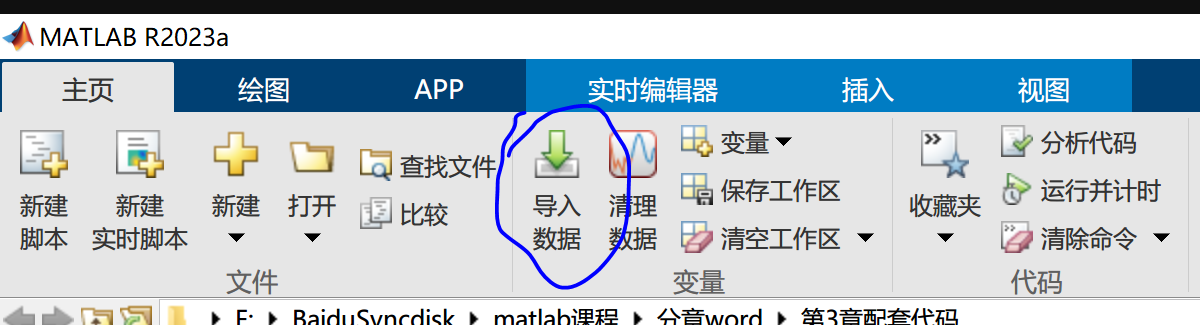

配套的讲解视频可在b站免费观看：

《MATLAB教程新手入门篇（数学建模清风主讲，适合零基础同学观看）》

[https://www.bilibili.com/video/BV1dN4y1Q7Kt/](https://www.bilibili.com/video/BV1dN4y1Q7Kt/)